**Sprawozdanie 12 Adam Frydel**

**Wstęp**

Podczas laboratoriów zajmowałem się modelowaniem układów regulacji w systemach z ujemnym sprzężeniem zwrotnym. Celem było stworzenie i analiza modeli regulacji poziomu cieczy oraz temperatury w zbiorniku. Głównym zadaniem było odpowiednie wyregulowanie regulatora PI zarówno w przypadku utrzymania zadanej objętości cieczy (sterowanie odpływem/ zaworami) oraz zadanej temperatury tej cieczy. 

W pierwszej kolejności , obliczałem uchyb regulacji e(t) jako różnicę między wartością zadaną a wartością sygnału zwrotnego . Następnie analizowałem wpływ regulatora na generowanie sygnału sterowania , który steruje elementem wykonawczym. Przeprowadziłem symulacje działania dwóch pętli regulacyjnych:

- **LC (Level Controller):** Regulacja poziomu cieczy w zbiorniku za pomocą zaworu. Wykorzystałem model zaworu sterowanego uchyłem regulacji, gdzie stopień otwarcia zaworu zmieniał się w zależności od odczytanego poziomu cieczy.

- **TC (Temperature Controller):** Regulacja temperatury cieczy w zbiorniku poprzez kontrolę mocy grzałki. Zmiany mocy zależały od różnicy między temperaturą zadaną a zmierzoną.

Dzięki temu nauczyłem się, jak implementować i dostrajać układy regulacji, zapewniając stabilność oraz precyzyjne działanie systemu mimo obecności zakłóceń zewnętrznych.

**1.Stworzenie substemu oraz zdefiniowanie zmiennych**

   Na początku winny byłem utworzyć subsystem jako wcześniej już zaimplementowany zbiornik_sys z ćwiczenia Linearyzacja układów nieliniowych. Prezentował się on jak poniżej. Oczywiście w zadaniu uwzględniłem funkcje zbiornik_stan oraz zbiornik_sfcn, która stanowiła moją s-funkcję. Ich kod przedstawię na końcu sprawozdania.  Subsystem stworzyłem przyciskiem Create Subsystem.       

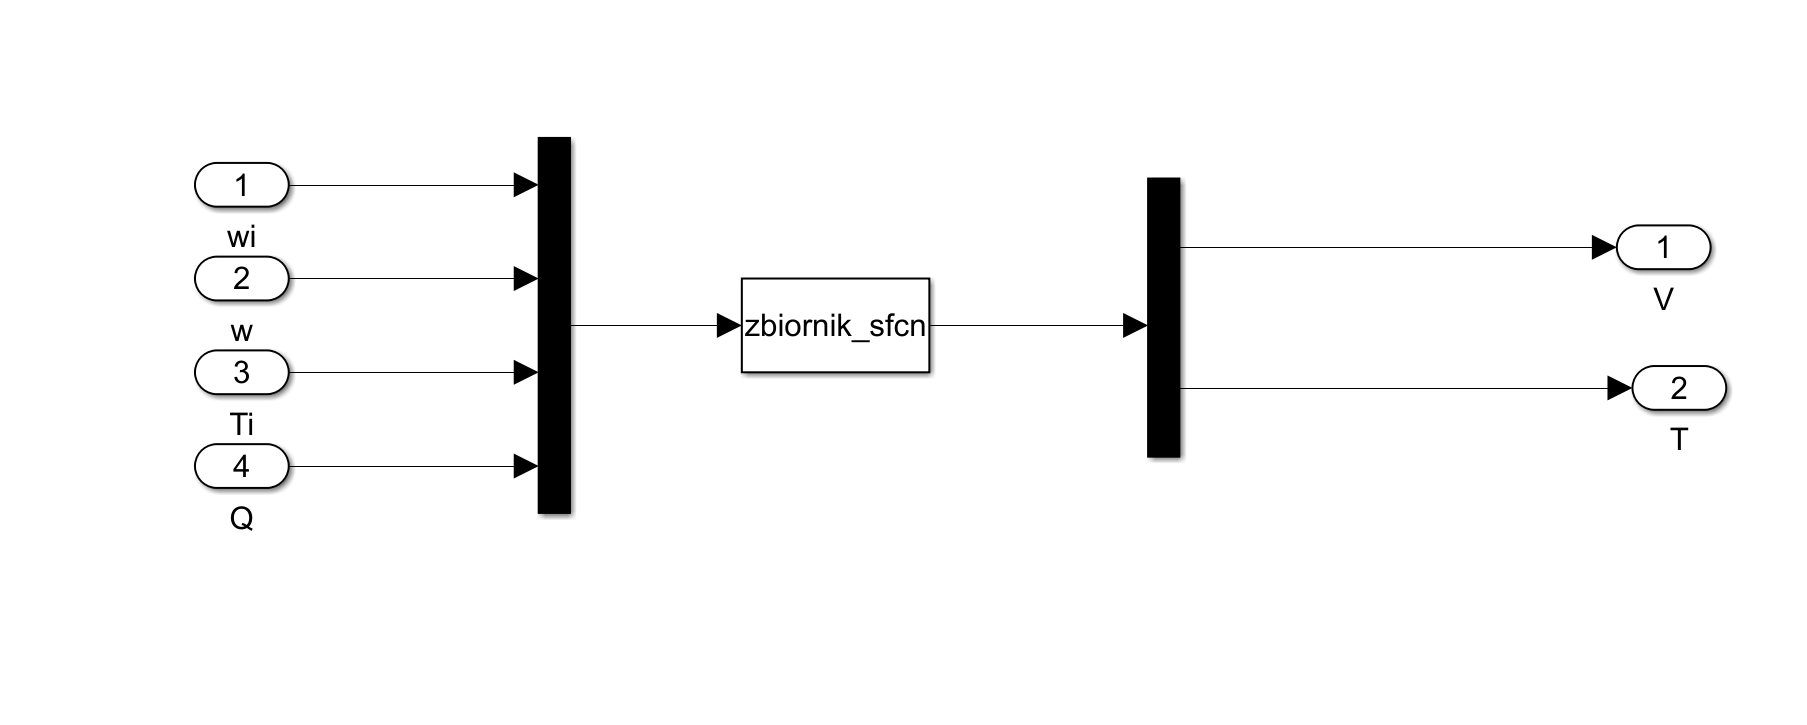

Poniżej zdefiniowałem również wszystkie potrzebne do wykonania zmienne, których wartości zostały wypisane w konspekcie. Posłużyłem się również wartościami początkowymi temperatury oraz objętości cieczy, które pobrałem z laboratorium o Linearyzacji.

wi = 0.4;
Ti = 293;
Qust = 16800;
Vzad = 0.04;
T_0 = 293;
V_0 = 0.04;
Tzad = 305;


**2.Sprzężenie zwrotne dla objętości**

Moim następnym zadaniem okazało się zbudowanie układu, który pozwoliłby na utrzymanie określonej zmienną Vzad objętości cieczy. Zadanie zrealizowałem łącząc wyjście V określające aktualną objętość z minusem sumatora natomiast Vzad z plusem sumatora. W ten sposób na wyjściu sumatora uzyskiwałem błąd, który podłączyłem do wejścia regulatora PI.

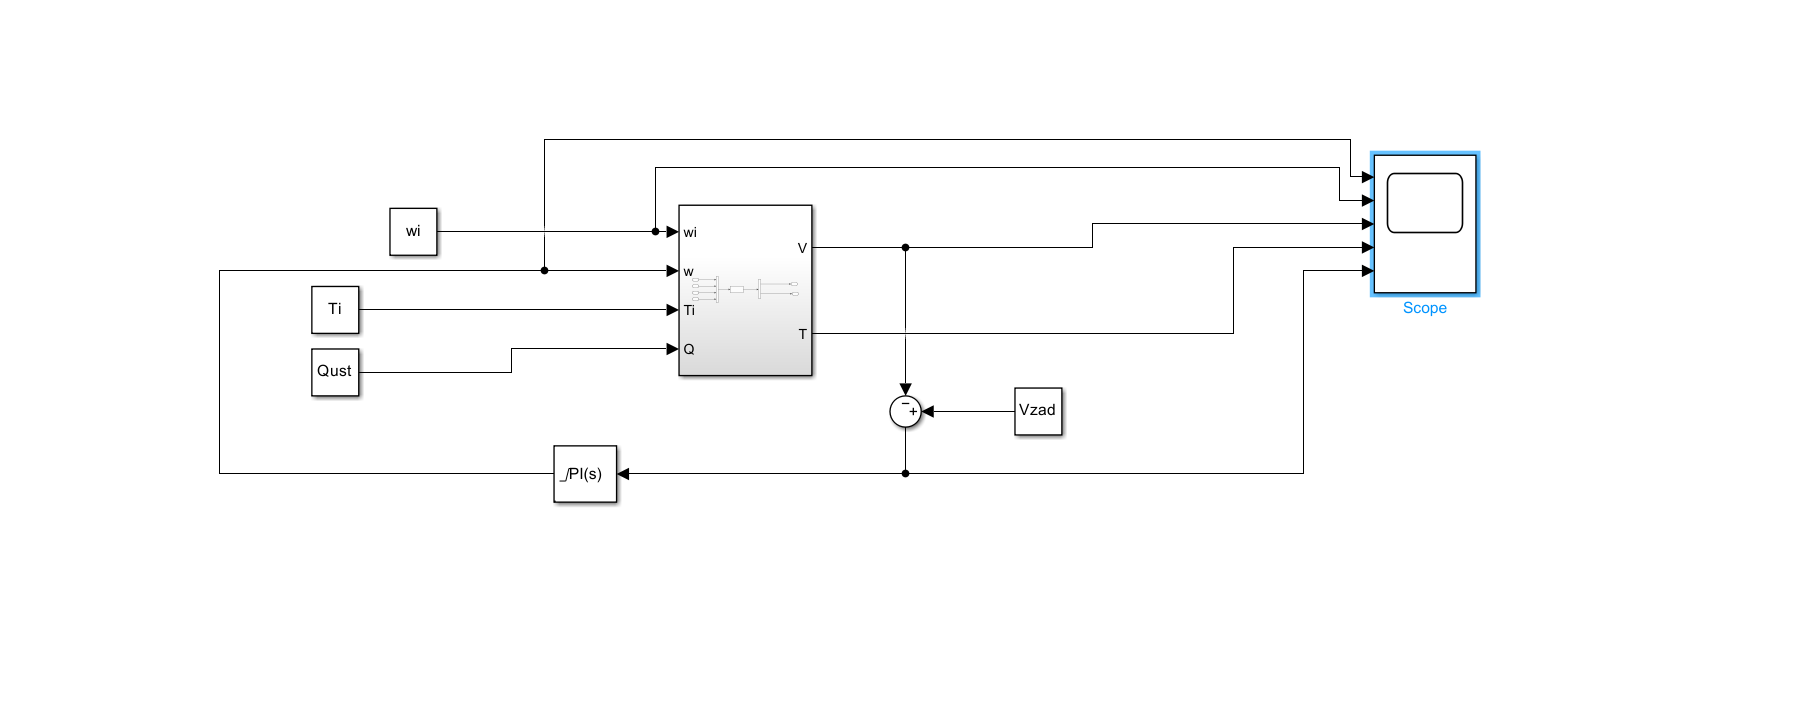

Zgodnie z treścią skryptu uzupełniłem bloczek PID Controller. Wstawiłem za P wartość ujemną ponieważ układ zachowywałby się odwrotnie niż oczekiwano dla dodatniej wartości przykładowo zamykałby zawór gdyby objętość była za duża co jest sprzeczne z logiką.

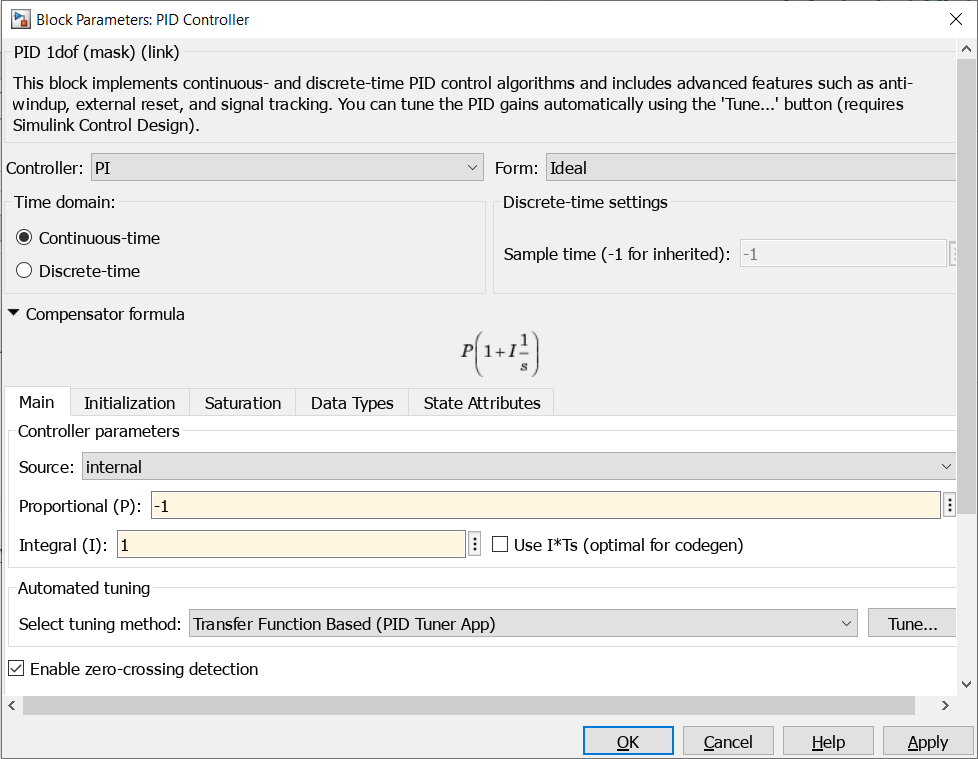

Odpowiednie wyjścia jak pokazałem na rysunku powyżej podpiąłem do oscyloskopu i po ustawieniu 400 próbek dla symulacji i przyciśnięciu przycisku Run mogłem już w pełnej krasie obserwować zachowanie różnych wartości na wykresach. Wyniki przedstawiłem poniżej.

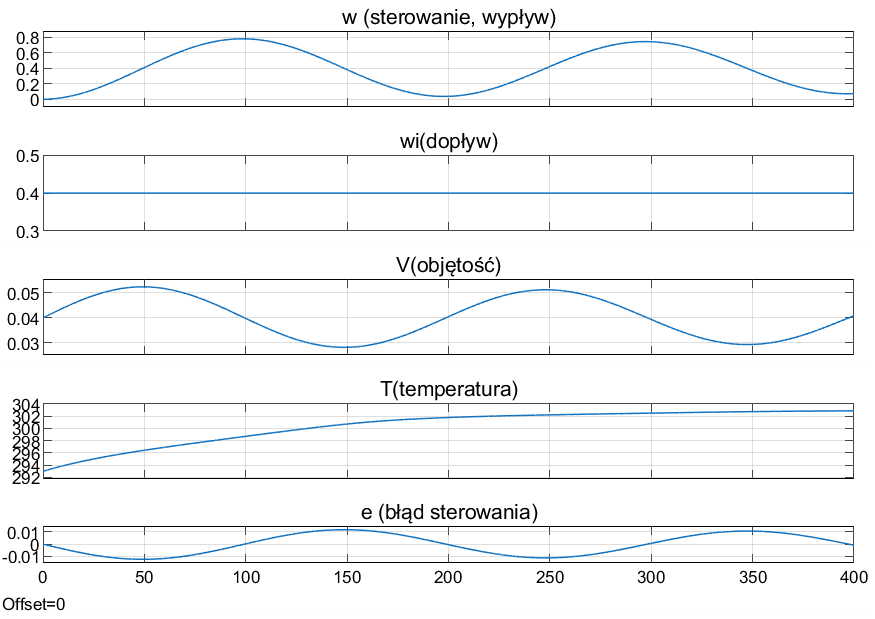

Jak można zauważyć, przy domyślnych ustawieniach regulatora sterowanie odbiega od oczekiwań. Sygnał sterujący ma charakter oscylacyjny, co prowadzi do dużych zmian w objętości . Musiałem zatem odpowiednio nastawić regulator za pomocą przycisku Tune, aby zmiejszyć wahania i mieć większą kontrolę nad objętością.

**3. Ustawienie regulatora Tunem**

Odpowiednio operując suwakami Responce Time oraz Transient Behavior ustawiłem odpowiedź na raczej wolną oraz odporną z dopuszczalnym niewielkim przeregulowaniem. Następnie ustawiłem nowe parametry aby przenieść wyliczone parametry do bloku regulatora.

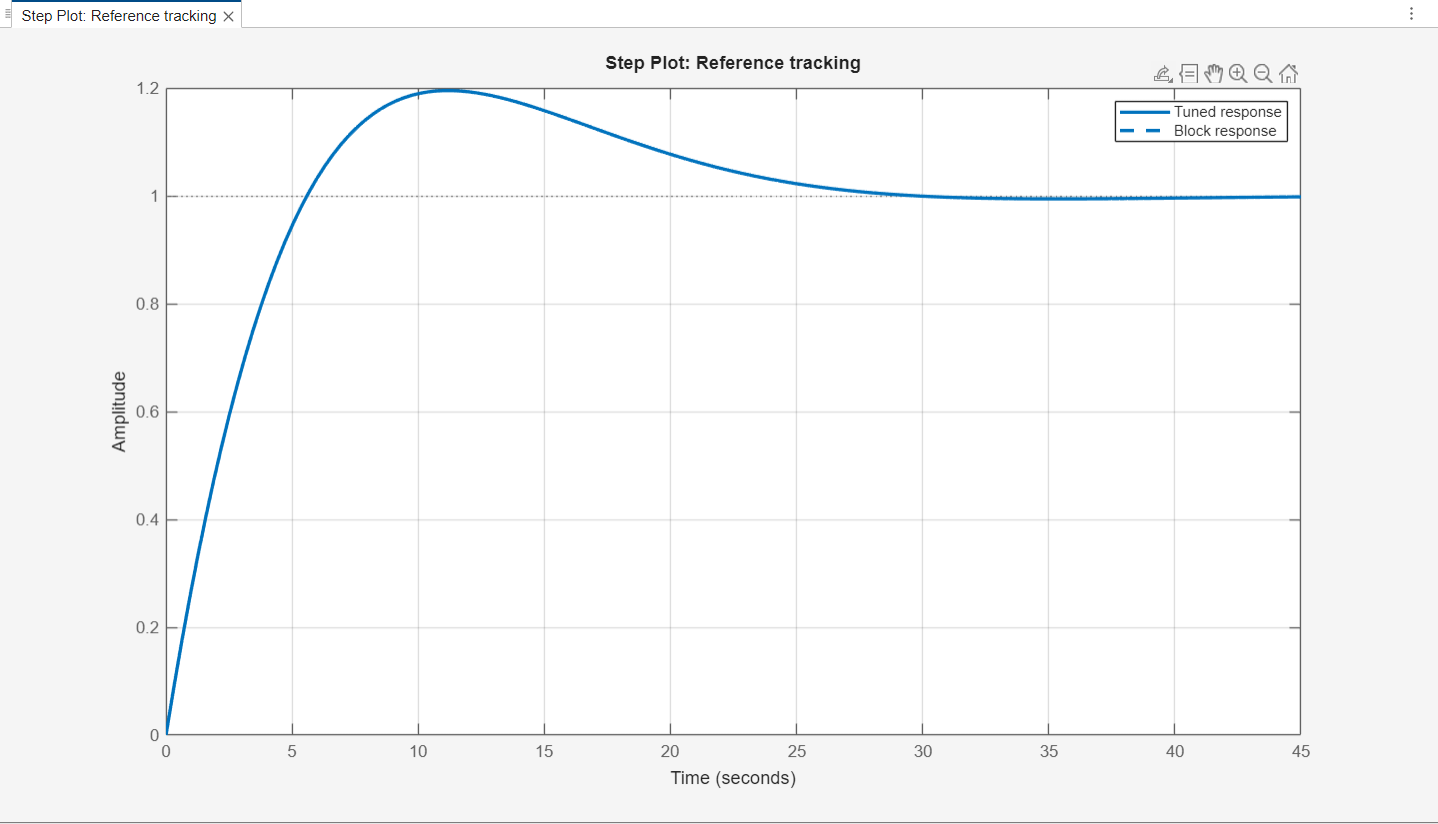

Po ponownym uruchomieniu symulacji wyniki prezentrowały się jak poniżej. Błąd sterowania szybko osiąga wartość zerową natomiast objętość osiąga zadaną wartość i się już na niej utrzymuje. Aktualnie miałem już dużo dokładniejszy model regulacji objętością ze sprzężeniem zwrotnym.

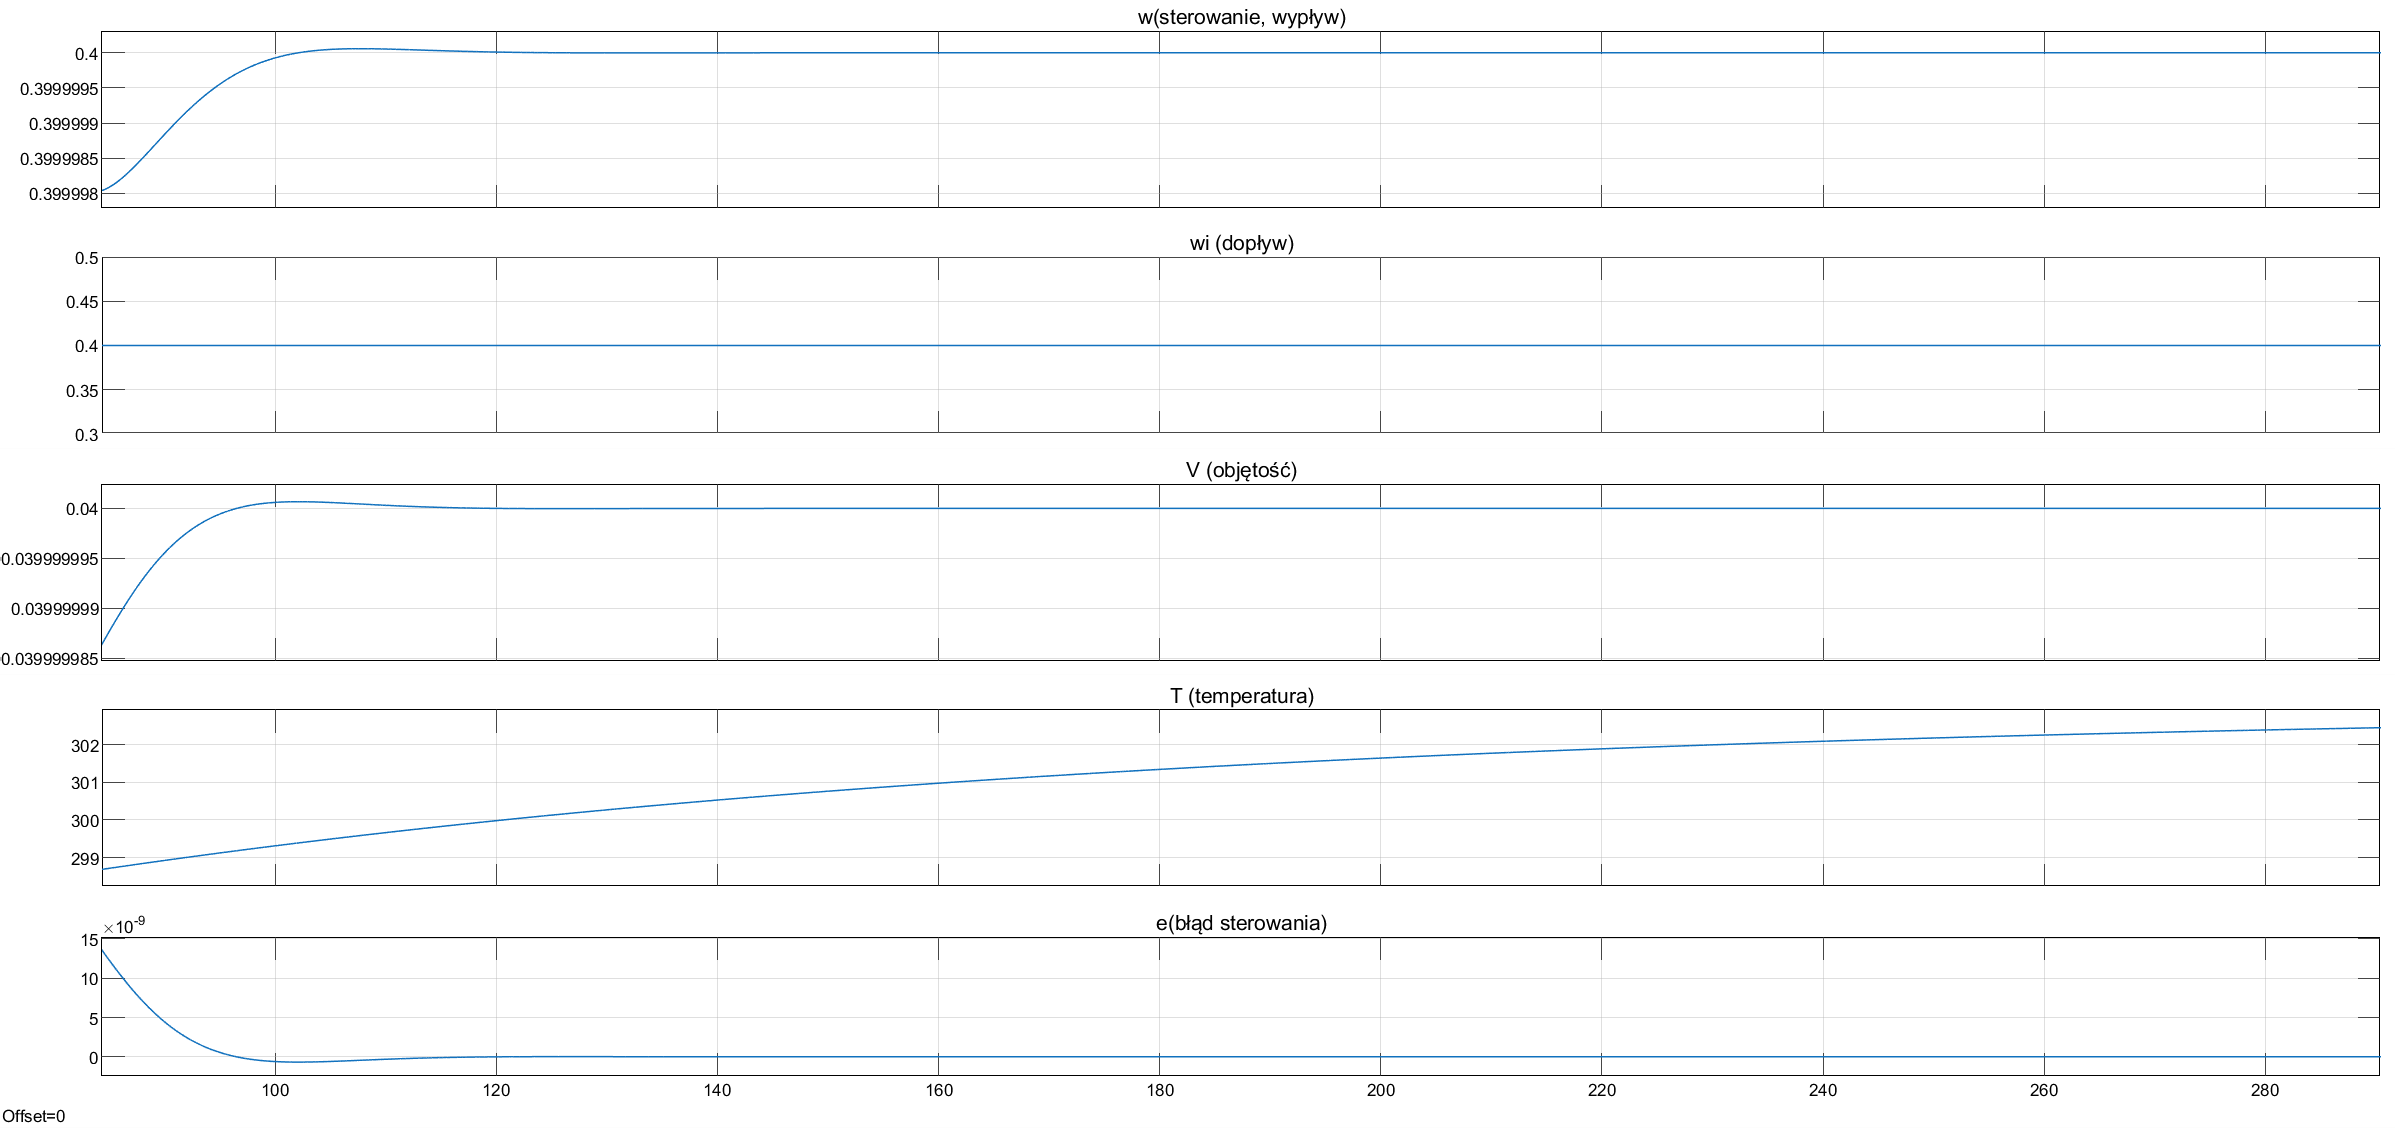

**4.Modelowanie zakłóceń**

Kolejnym krokiem było odpowiednie manipulowanie zakłóceniami czyli dostarczanymi porcjami wody do baniaka. W tym celu użyłem zamiast stałego wi użyłem bloczka Reapeating Sequence Stair. Tam wpisałem wektor wartości, które będą tylko raz po kolei (przez uprzednie odpowiednie dobranie ilości próbek) zakłócać wartości V objętości która ma być utrzymywana na zadanym poziomie. Zadanie polegało na sprawdzeniu działania układu przy nałożeniu na niego dodatkowego balastu w postaci zakłóceń.

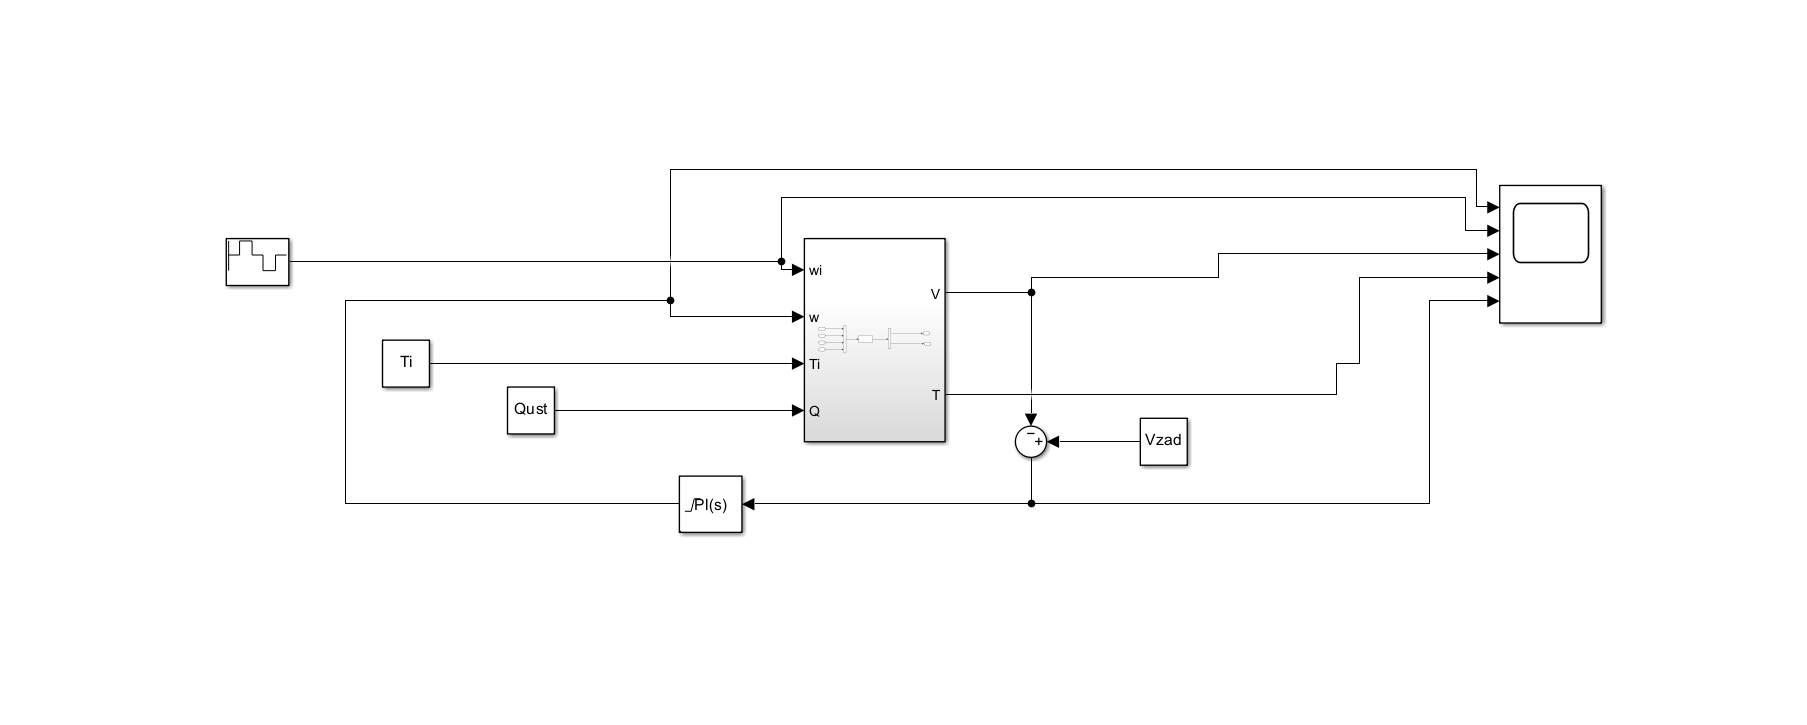

Dodatkowo poniżej przedstawiam w jaki sposób zmieniłem parametry symulacji do tego przebiegu.

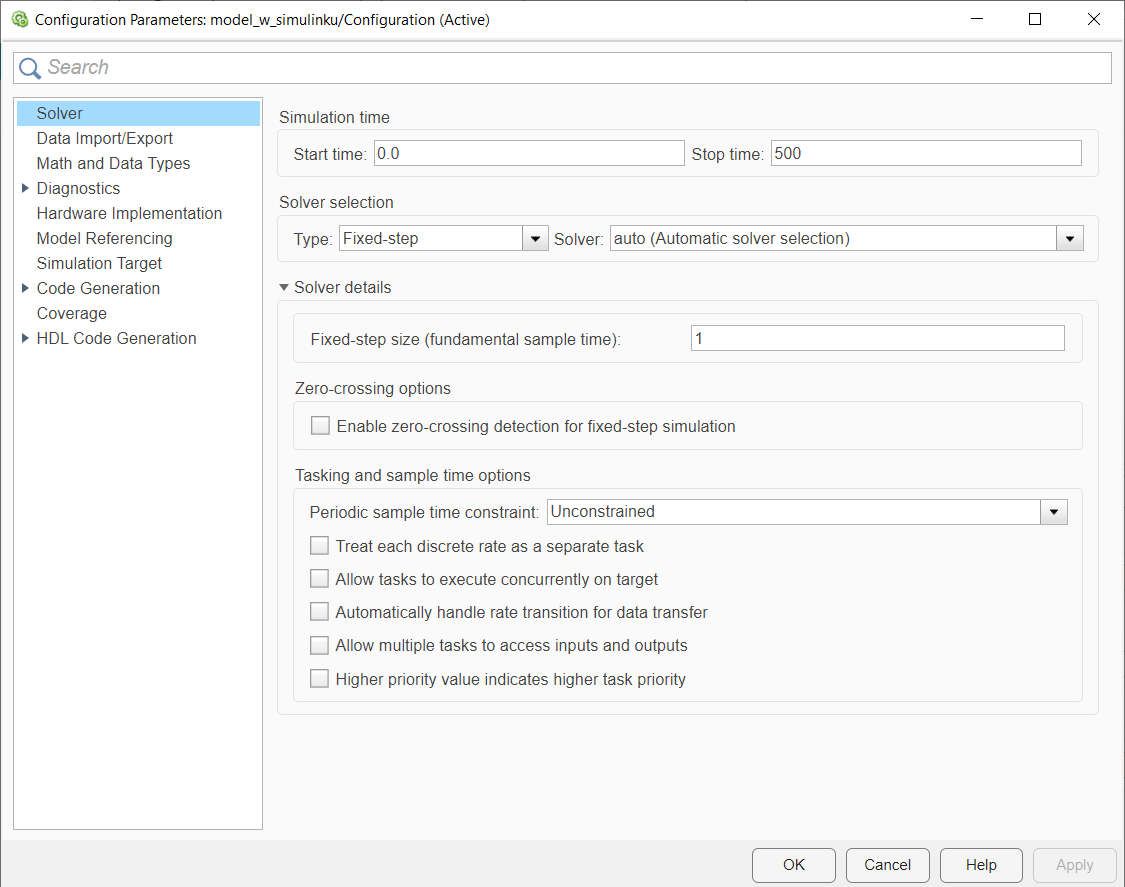

Wykresy prezentujące zachowanie poszczególnych zmiennych zaprezentowałem poniżej.

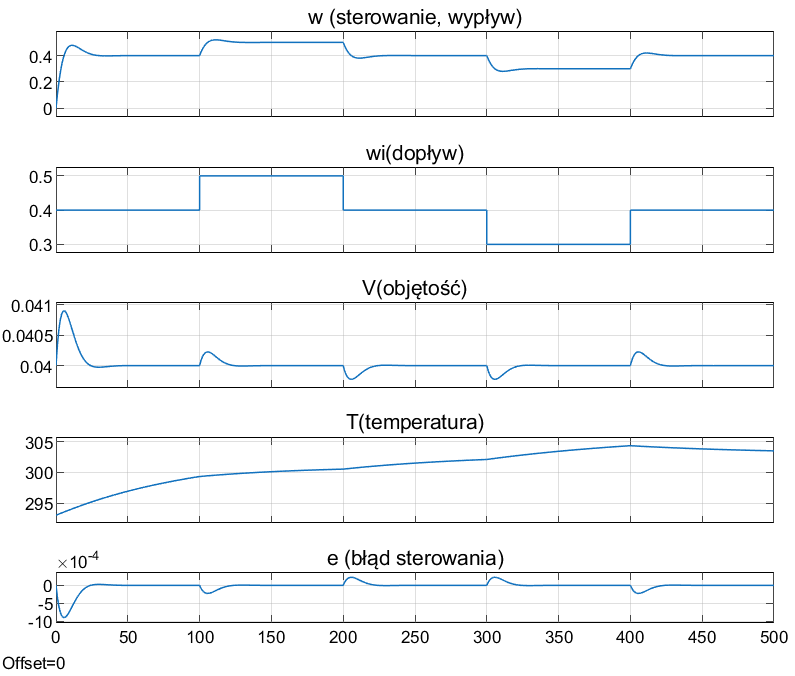

Jak widać nastawiony przeze mnie regulator całkiem dobrze radzi sobie z narzuconymi zakłóceniami. Oczywiście jeżeli wektor zakłóceń będzie zawierać większe wartości to wówczas błąd oraz czas stabilizacji objętości będzie się zwiększać.Tak samo będzie jeżeli Vzad będzie odbiegać od wartości V_0 oraz wprowadzanych zakłóceń.

**5.Wyregulowanie temperatury cieczy**

W tym zadaniu musiałem dodać do modelu regulator PI, który odpowiada za regulację temperatury cieczy w zbiorniku. Regulator ten obliczał uchyb regulacji jako różnicę między temperaturą aktualną T a temperaturą zadaną Tzad, a następnie na podstawie tego uchybu generował sygnał sterujący mocą grzałki Q. Do modelu wprowadziłem również zakłócenie w postaci temperatury wody z wodociągu Ti, która wpływała na proces grzania.

Testowałem działanie regulatora, zmieniając jego parametry oraz wartości zadane Tzad i zakłócenia Ti, aby sprawdzić wpływ tych czynników na stabilność oraz skuteczność regulacji. Celem było osiągnięcie szybkiej i precyzyjnej stabilizacji temperatury przy minimalnych wahaniach. Uzyskany przeze mnie układ wygląda jak poniżej.

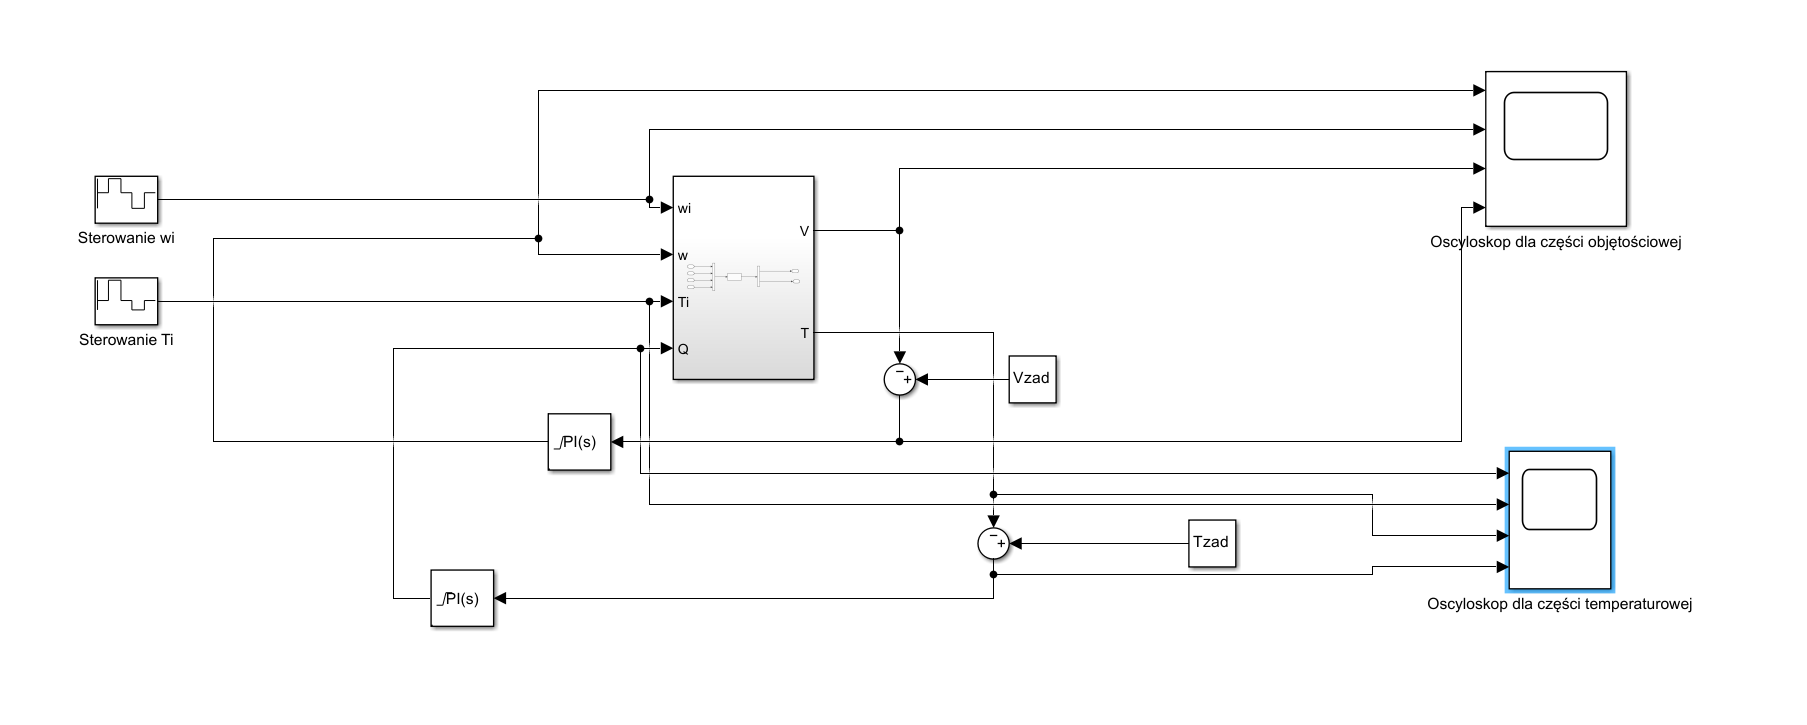

Poniżej przedstawiam wynik dla Oscyloskopu dla części objętościowej

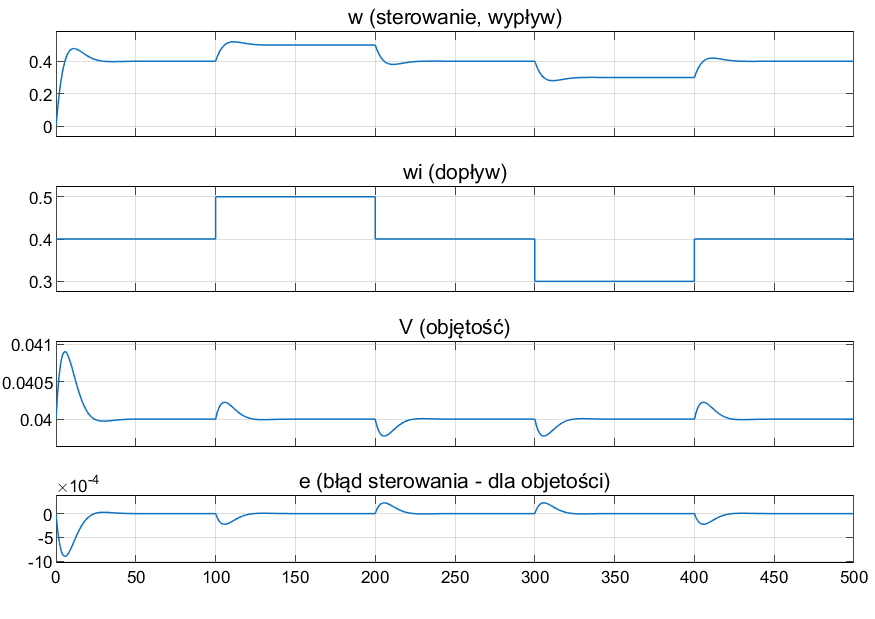

Poniżej przedstawiam wynik dla Oscyloskopu dla części temperaturowej.

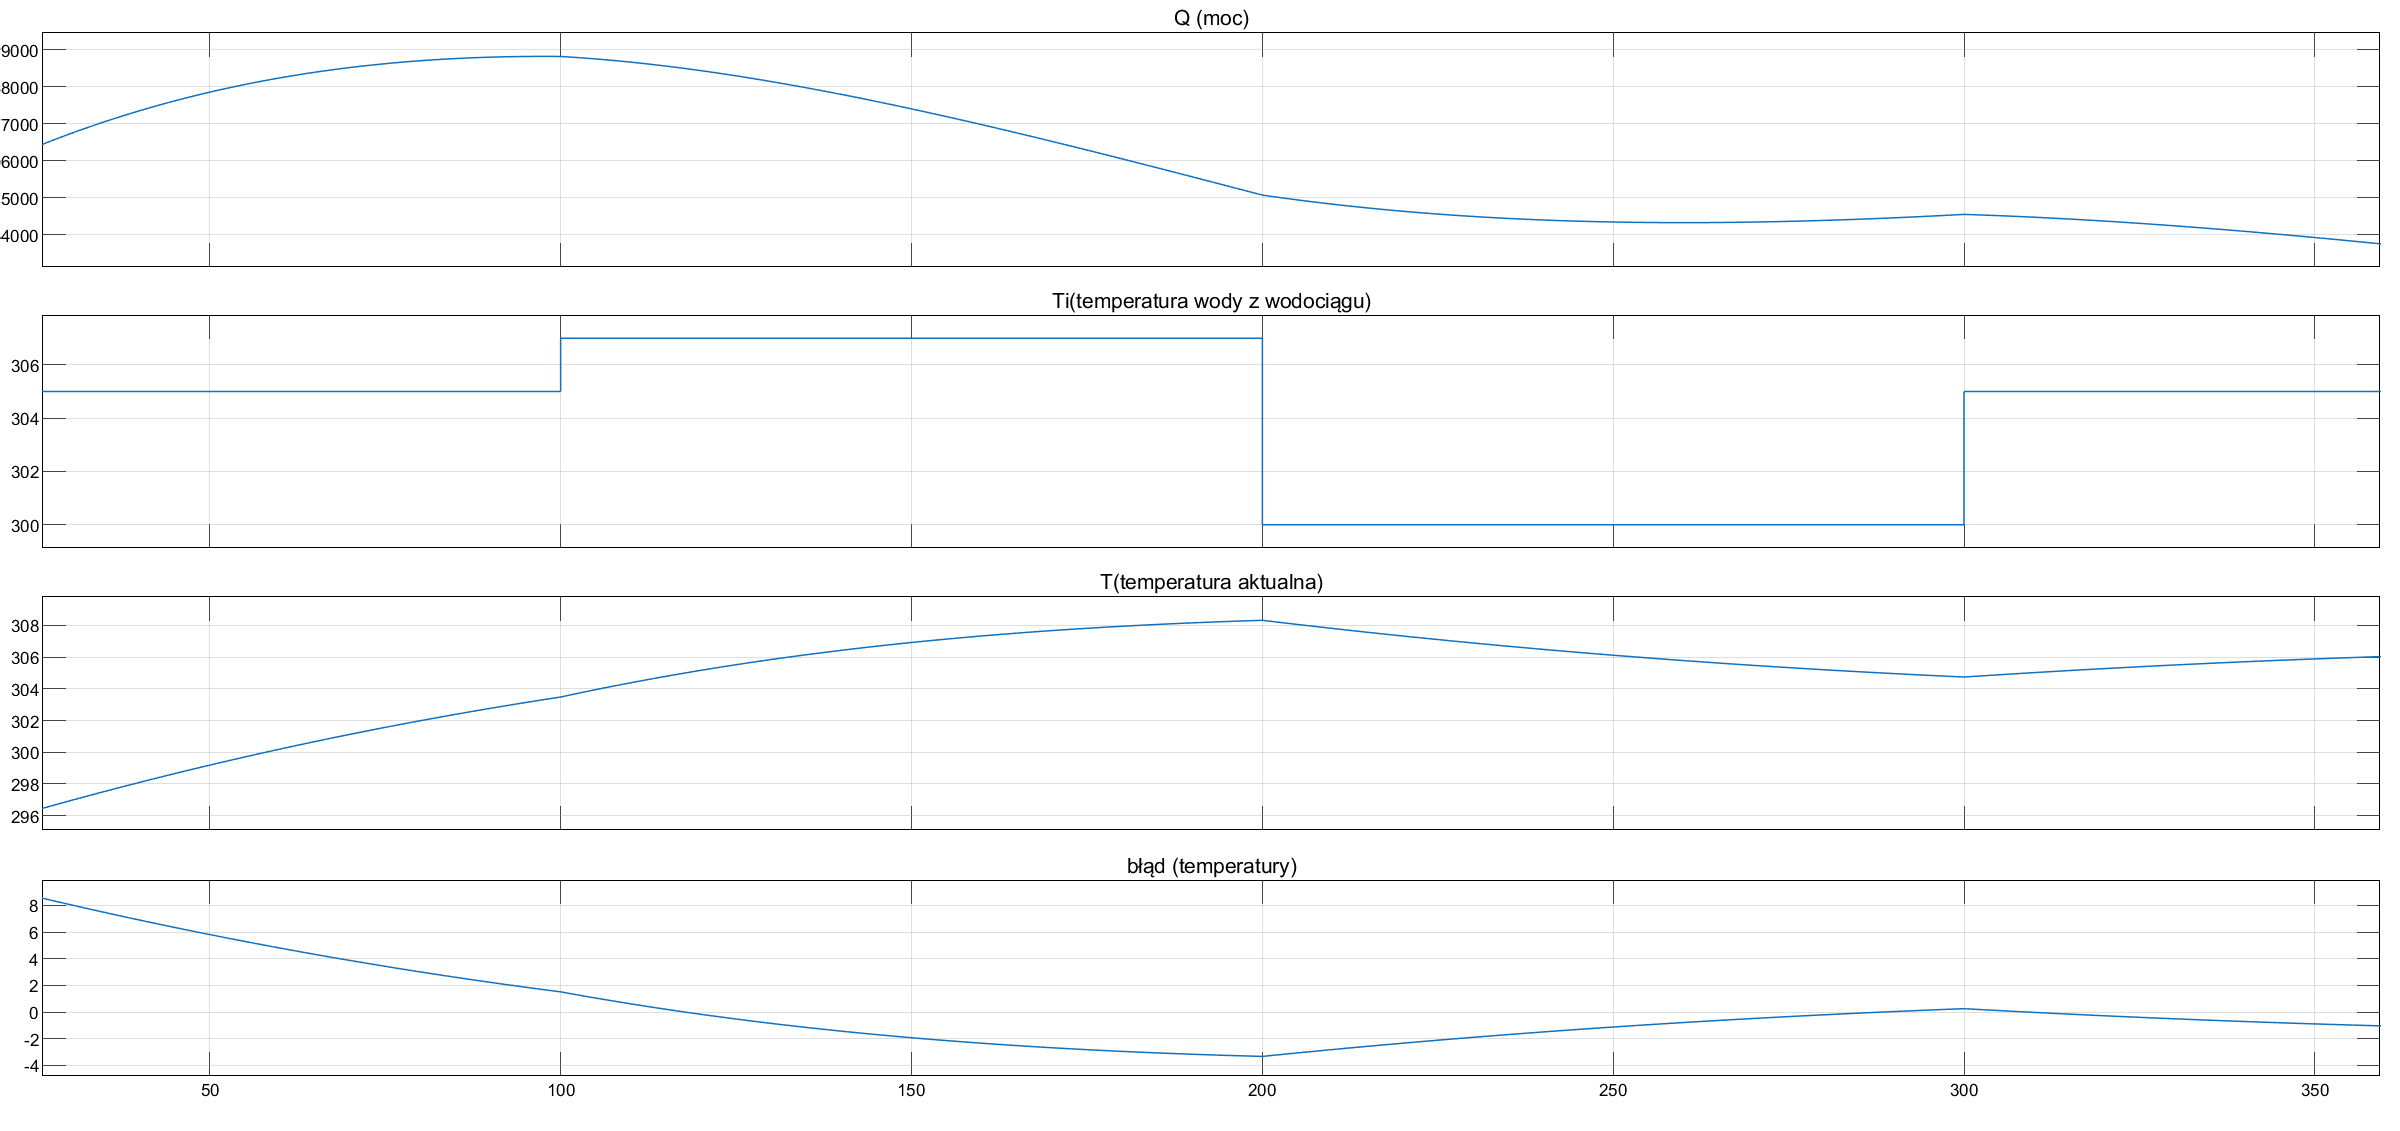

Regulator PI powinien precyzyjnie doprowadzać temperaturę T do wartości zadanej Tzad, kompensując zakłócenia, takie jak zmiany temperatury wody z wodociągu Ti. Przy zmianach Tzad regulator dostosowuje moc grzałki Q, eliminując uchyb regulacji. Dobór parametrów regulatora wpływa na szybkość reakcji i stabilność – zbyt wysokie wartości mogą powodować oscylacje, a zbyt niskie spowalniać regulację. Właściwie dobrane nastawy zapewniają szybkie osiągnięcie stanu ustalonego bez dużych wahań temperatury, nawet przy zmiennych zakłóceniach.

Przez brak chłodzenia układ jest tak na prawdę zdany na pasywne obniżanie temperatury. Grzałka jest w stanie tylko pomóc w przypadkach kiedy temperatura wody jest za niska. Jednak nastawiony przeze mnie regulator całkiem dobrze sprawdzał się w sytuacjach kiedy temperatura wody z wodociągu była zbliżona do temperatury zadanej wody.

function dx = zbiornik_stan(t,x,wi,w,Ti,Q)
% Argumenty wejściowe:
% t - czas
% x - wektor stanu układu
% wi - dopływ
% w - wypływ
% Ti - temperatura cieczy dopływającej
% Q - moc dostarczana (grzanie)
%----------------------------- zmienne stanu ------------------------------
x1 = x(1); % objętość
x2 = x(2); % temperatura
%------------------------------- parametry --------------------------------
C = 4200; % ciepło właściwe [J/(Kg*K)]
ro = 1000; % gęstość [kg/m3]
%%---------------------------- równania stanu -----------------------------
dx1 = 1 / ro * (wi-w);
dx2 = wi * (Ti - x2) / (ro * x1) + Q / (ro * x1 * C);
dx = [dx1;dx2]; % pochodne stanu

function [sys,x0,str,ts]=zbiornik_sfcn(t,x,u,flag,V0,T0)
switch flag
case 0 % inicjalizacja
str = [];
ts = [0 0];
s = simsizes;
s.NumContStates = 2; % liczba stanów ciągłych
s.NumDiscStates = 0; % liczba stanów dyskretnych
s.NumOutputs = 2; % liczba wyjść
s.NumInputs = 4; % liczba wejść
s.DirFeedthrough = 0; % wejście nie przenosi się bezpośrednio na wyjście
s.NumSampleTimes = 1; % czas próbkowania
sys = simsizes(s);
x0 = [V0, T0];
case 1 % pochodne
wi = u(1);
w = u(2);
Ti = u(3);
Q = u(4);
sys = zbiornik_stan(t,x,wi,w,Ti,Q);
case 3 % wyjście
sys = x;
case {2 4 9}
sys =[];
otherwise
error(['unhandled flag =',num2str(flag)]);
end

**6. Podsumowanie**

Podczas laboratoriów zajmowałem się modelowaniem układów regulacji poziomu cieczy i temperatury w zbiorniku za pomocą regulatorów PI. W pierwszej części stworzyłem układ regulacji objętości, gdzie błąd między wartością zadaną a aktualną objętością sterował zaworem. Następnie dostosowałem nastawy regulatora, aby zmniejszyć oscylacje i poprawić stabilność.

W drugiej części modelowałem regulację temperatury cieczy, uwzględniając zakłócenia w postaci zmiennej temperatury wody dopływającej. Regulator PI generował sygnał sterujący mocą grzałki, kompensując różnice między temperaturą zadaną a rzeczywistą. Testowałem działanie układu dla różnych parametrów i zakłóceń, osiągając szybkie i stabilne działanie.

Oba modele pokazały skuteczność regulatora PI w zapewnianiu stabilności i precyzji, przy czym kluczowe było właściwe dostrojenie parametrów, które wpływało na czas odpowiedzi i wahania sygnałów.